%  Second EDP tutorial (embedding dimensions handling)
clear all
close all
rng('default');
rng(1);

% time-series generation
disp('*****************************************************')

*****************************************************


disp('Data generation and structure')

Data generation and structure


disp('*****************************************************')

*****************************************************


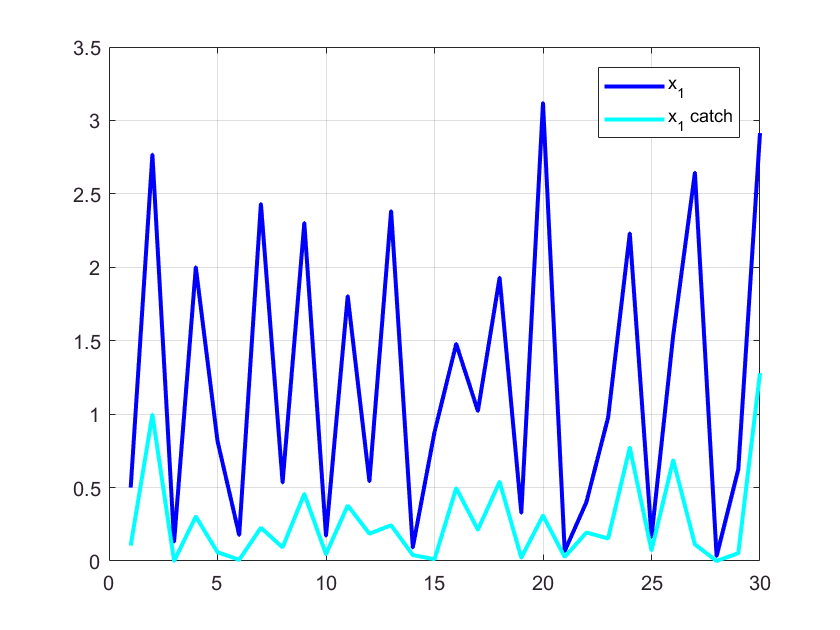


% time-series length
T = 30;

% default EDM structure
[mdlstruct] = init_mdl_struct(1); % the input is the number of available species data

% data generation using a ricker model
% param={[0.1 0.1],[3 0.5; 0.8 3],[3 3]}; % ricker model parameters
param={[0.01 0.01],[2 0.5; -0.3 2],[3 3]}; % ricker model parameters
mdlstruct.model = @(x,u,is_det) dyn_ricker(x,u,is_det,param);


% random control between 0 and 0.5
u = [rand(T,1)/2 zeros(T,1)];

% data generation
[mdlstruct.data,mdlstruct.control_data] =  generate_data(mdlstruct.model,[0.5 0.5],u,T);

% Here we know that there are 2 species, we need to precise the name of the second for the simulation figures
% !!! 
mdlstruct.name={'x_1','x_2'};

%different kinds of control exist, we need to specify which one we use here
mdlstruct.control_type =  'rate';
mdlstruct.control_param =  [1];

% data display
data_show(mdlstruct)


% we specify the number of lags used here
% here, we specify the number of time lags used for each variables
% 0 means that the variable is not used in the prediction
mdlstruct.n_lags = [2 0]; % th: 36.2, sim: 30.64 

% after running the code, try now mdlstruct.n_lags = [2 0];



% GP regression
disp('*****************************************************')

*****************************************************


disp('GP fitting')

GP fitting


disp('*****************************************************')

*****************************************************


% this step can be skipped if a model already exists, otherwise a GP is
% fitted to the data
% fills the field mdlstruct.model with the fitted gp
% fills the field mdlstruct.model_stats with statistics computed during the
% GP regression

% default gp structure
mdlstruct.gp = init_gp();

% we now fit the gp with the data in mdlstruct
mdlstruct = fit_gp(mdlstruct);

% gp display
gp_show(mdlstruct)

**********************************************************
Negative log likelihood: 1.3399
 
Lengthscale parameters:
1.8428     0.74148
 
Scaled In-Sample error: 0.03922
 
Scaled Out-of-Sample error: 0.070358
 
**********************************************************



% Optimal control problem
disp('*****************************************************')

*****************************************************


disp('Optimal control problem structure')

Optimal control problem structure


disp('*****************************************************')

*****************************************************



% Discount factor
optstruct.discount_factor=0.95;

% Objective weights
optstruct.weights = [1];


% Reward function
% The instantaneous reward function is a handle function.
% The input are the current variables, the controls and the weight for each
% dimension
% The output are the total weighted reward, the unweighted reward on each
% dimension, and the weighted reward on each dimension

%>>> Example 1 <<<<
% use of an existing function
optstruct.reward = @(x,u,w) reward_harvest_all(x,u,w);

% Temporal difference learning
disp('*****************************************************')

*****************************************************


disp('EDP using Temporal difference learning')

EDP using Temporal difference learning


disp('*****************************************************')

*****************************************************


% default  td structure
dpstruct=init_td(mdlstruct);

%  run the td algorithm, using the gp regression
 [dpstruct] = td_learning(mdlstruct,optstruct,dpstruct,'gp');

 % control maps
 disp('Control maps given by the EDP algorithm')

Control maps given by the EDP algorithm


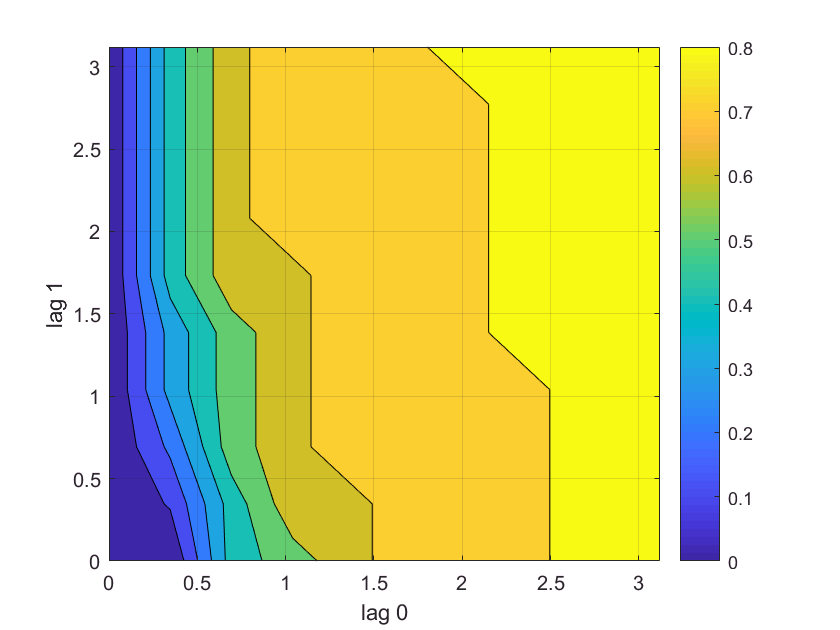

td_show(mdlstruct,optstruct,dpstruct)


% controlled trajectories
t_max = 50; % time length
n_traj = 10; % number of trajectories
start_x = 'mean'; % starting point
is_disp = 1; % display the trajectories result
disp('Controlled trajectories following the EDP policy')

Controlled trajectories following the EDP policy


**********************************************************
Theorical value: 36.2272
 
Simulated mean value: 31.5772
 
**********************************************************


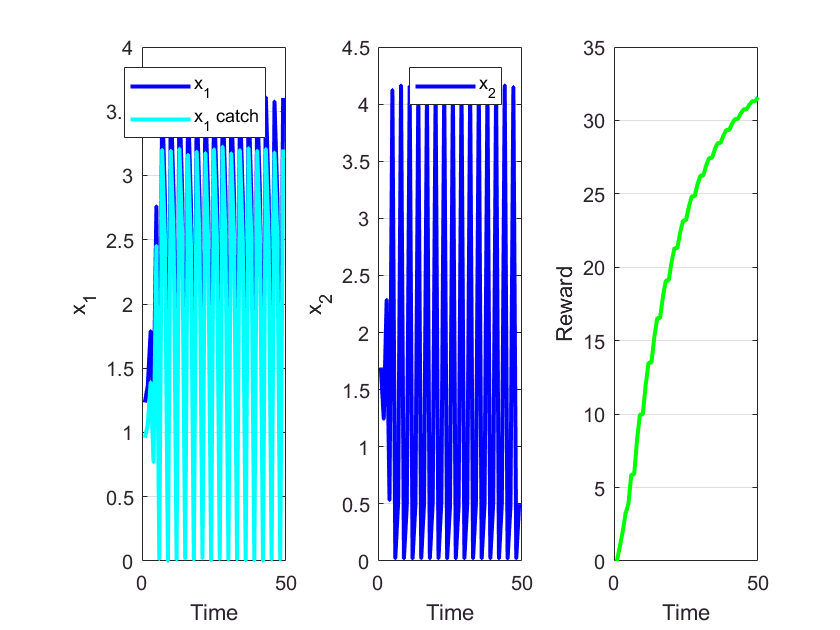

traj = sim_trajectories(mdlstruct,optstruct,dpstruct,t_max,n_traj,start_x,is_disp);